# 插值可以用于缺失**数据补全处理**、对现有数据进行平滑处理以及进行预测等.

# interp1表一维线性插值

# interp2表二维线性插值

## spline 样条插值

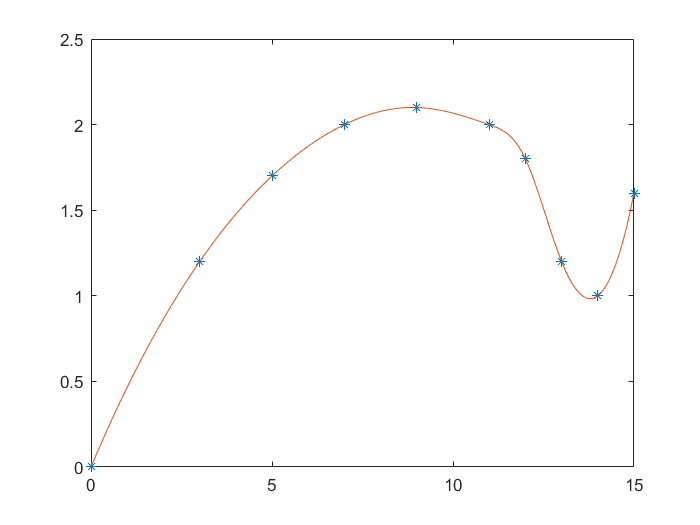

clear
clc
x = [0, 3, 5, 7, 9, 11, 12, 13, 14, 15];
y = [0, 1.2, 1.7, 2.0, 2.1, 2.0, 1.8, 1.2, 1.0, 1.6];
figure(1)
plot(x,y,'*')
hold on
x1 = 0:0.1:15;
y1 = interp1(x, y, x1, 'spline')  ;
plot(x1, y1)

## linear 线性插值

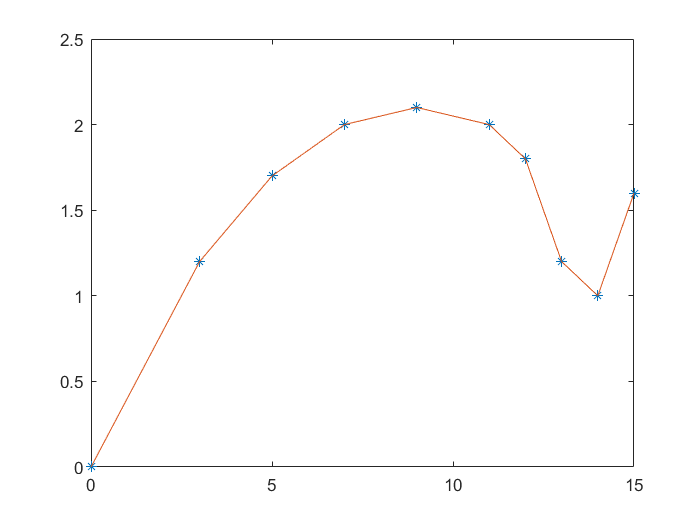

clear
clc
x = [0, 3, 5, 7, 9, 11, 12, 13, 14, 15];
y = [0, 1.2, 1.7, 2.0, 2.1, 2.0, 1.8, 1.2, 1.0, 1.6];
figure(2)
plot(x,y,'*')
hold on
x1 = 0:0.1:15;
y1 = interp1(x,y,x1,'linear');
plot(x1,y1)

## pchip 分段三次艾尔米特插值

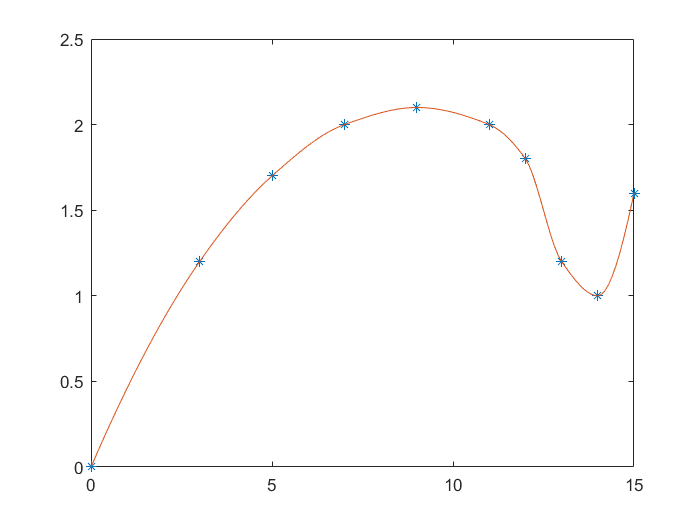

clear
clc
x = [0, 3, 5, 7, 9, 11, 12, 13, 14, 15];
y = [0, 1.2, 1.7, 2.0, 2.1, 2.0, 1.8, 1.2, 1.0, 1.6];
figure(3)
plot(x,y,'*')
hold on
x1 = 0:0.1:15;
y1 = interp1(x,y,x1,'pchip');
plot(x1,y1)

## nearest 最临近插值

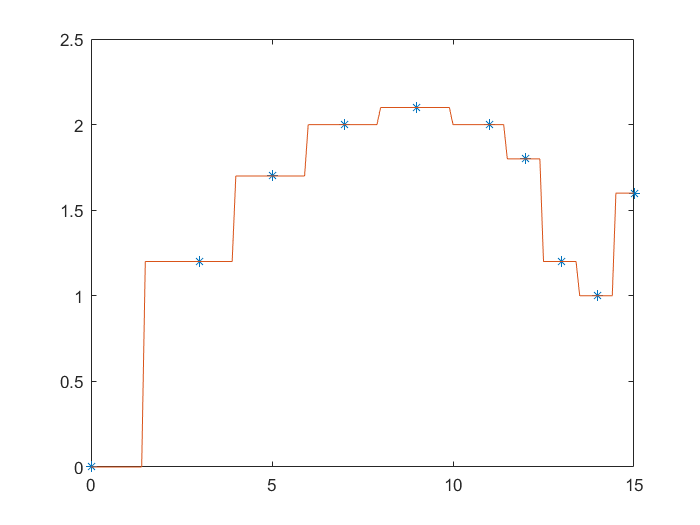

clear
clc
x = [0, 3, 5, 7, 9, 11, 12, 13, 14, 15];
y = [0, 1.2, 1.7, 2.0, 2.1, 2.0, 1.8, 1.2, 1.0, 1.6];
figure(4)
plot(x,y,'*')
hold on
x1 = 0:0.1:15;
y1 = interp1(x,y,x1,'nearest');
plot(x1,y1)

## Newton_Interpolation 牛顿插值

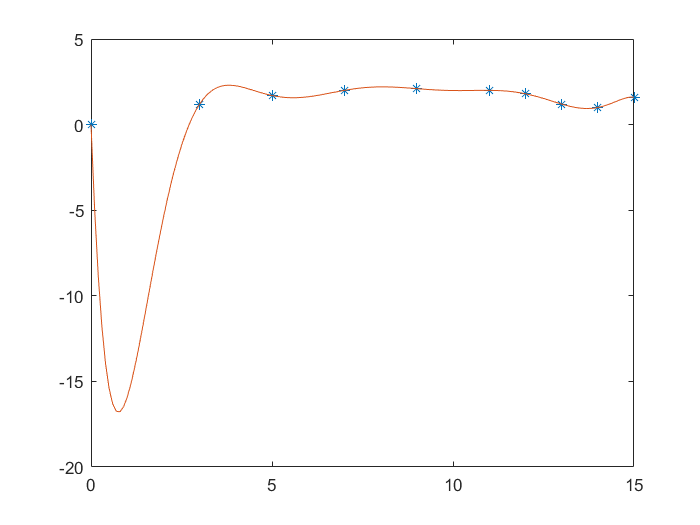

clear
clc
x = [0, 3, 5, 7, 9, 11, 12, 13, 14, 15];
y = [0, 1.2, 1.7, 2.0, 2.1, 2.0, 1.8, 1.2, 1.0, 1.6];
figure(5)
plot(x,y,'*')
hold on
x1 = 0:0.1:15;
scale = size(x1);
scale = scale(:,2);
y1 = zeros(1,scale);
n = size(x);
n = n(:,2);
C = [x;y]';
for i = 1:1:scale
    temp = x1(:,i);
    y1(:,i) = Newton_Interpolation(temp,n-2,C);
end
plot(x1,y1)

## Newton_Interpolation 牛顿插值函数

function y = Newton_Interpolation(x,n,C)

[r,c]=size(C);
number=r*c;
if number~=2*(n+2)
    error("输入节点不足")
end

if nargin~=3
    error("输入参数不足")
end

for j=3:n+3
    for i=j-1:n+2
        C(i,j)=( C(i,j-1)-C(i-1,j-1) )/( C(i,1)-C(i+2-j,1) );
    end
end

y=0;
for i=1:n+2
    S=1;
    for j=i-1:-1:1
        S=S*(x-C(j,1));
    end
y=y+C(i,i+1)*S;
end

K=1;
R=1;
for i=1:n+1
    K=K*(x-C(i,1));
end
R = abs(C(n+2,n+3)*K);

end